Parameters = [0.5,0.8,100,1];

clockPeriod = 4e-9;
halfPeriod = 1/(2*Parameters(1)*1e6);
halfPeriod_actual = clockPeriod * round(halfPeriod/clockPeriod);
A_Actual = 1e-6/(halfPeriod_actual*2); %MHz

pulseTime = halfPeriod_actual*2*Parameters(3); % seconds
nTicks = int32(pulseTime/clockPeriod);
time = 0:nTicks-1;
wave = zeros(1,nTicks);
nTicksHalfPeriod = nTicks/Parameters(3);
for n = 1:Parameters(3)
    centre = (n*nTicksHalfPeriod) - round(nTicksHalfPeriod/2);
    width = Parameters(2)*nTicksHalfPeriod;
    low = round(centre - width/2)+1;
    high = round(centre + width/2);
    wave(low:high) = Parameters(4) * (-1)^n;
end

if sum(wave) < 0 || sum(wave) > 0 % Equalisation Pulse
    n = n+2;
    wave(end+1:end+2*nTicksHalfPeriod) = zeros(1,2*nTicksHalfPeriod);
    wave = circshift(wave,nTicksHalfPeriod);

    centre = (nTicksHalfPeriod) - round(nTicksHalfPeriod/2);
    width = Parameters(2)*nTicksHalfPeriod/2;
    low = round(centre - width/2)+1;
    high = round(centre + width/2);
    wave(low:high) = Parameters(4) * (-1)^(n+1);

    centre = (n*nTicksHalfPeriod) - round(nTicksHalfPeriod/2);
    width = Parameters(2)*nTicksHalfPeriod/2;
    low = round(centre - width/2)+1;
    high = round(centre + width/2);
    wave(low:high) = Parameters(4) * (-1)^(n+1);
else
    n = n+2;
    wave(end+1:end+2*nTicksHalfPeriod) = zeros(1,2*nTicksHalfPeriod);
    wave = circshift(wave,nTicksHalfPeriod);

    centre = (nTicksHalfPeriod) - round(nTicksHalfPeriod/2);
    width = Parameters(2)*nTicksHalfPeriod/2;
    low = round(centre - width/2)+1;
    high = round(centre + width/2);
    wave(low:high) = -Parameters(4) * (-1)^(n+1);

    centre = (n*nTicksHalfPeriod) - round(nTicksHalfPeriod/2);
    width = Parameters(2)*nTicksHalfPeriod/2;
    low = round(centre - width/2)+1;
    high = round(centre + width/2);
    wave(low:high) = Parameters(4) * (-1)^(n+1);
end

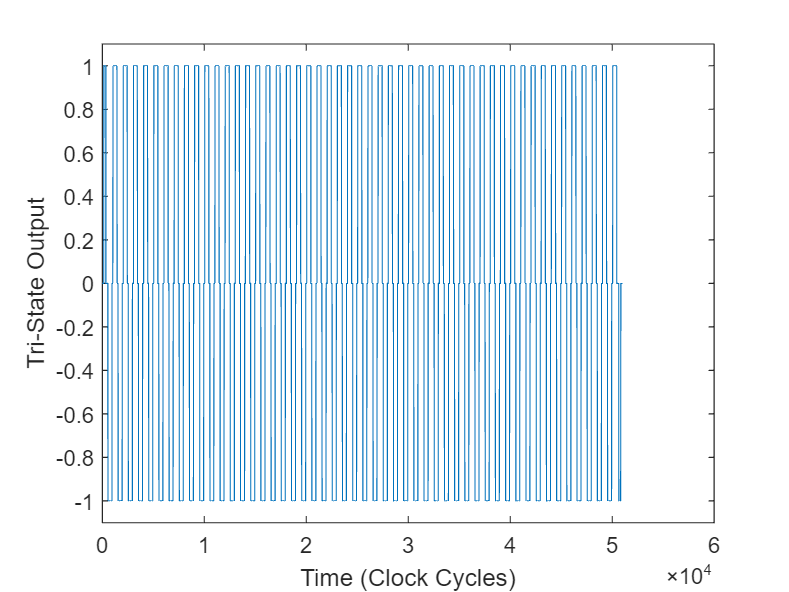


plot(wave)
xlabel('Time (Clock Cycles)')
ylabel("Tri-State Output")
ylim([-1.1,1.1])

Transmit_Time = halfPeriod_actual*Parameters(3)

Transmit_Time = 1.0000e-04